# Parameter estimation for auxiliary model 2

## Definition of the model

clear;clc;close all
ParNames =  {'\delta_0','\delta_1','\delta_2','\delta_3','\alpha_1','\alpha_2',...
    '\alpha_3','K'};%names for the parameters
VarNames = {'N_1','N_2','N_3','N_4','Pf_0','Pf_1','Pf_2','Pf_3','Pf_4','D'};%names for the state variables
OutNames = {'N_1','N_2','N_3','N_4','Pf_0','Pf_1','Pf_2','Pf_3','Pf_4','D'};%names for the outputs

FullNames = [VarNames,ParNames];
Range1 = zeros(10,2);%ranges for initial conditions
Range2 = [zeros(8,1),ones(8,1)];%ranges for parameters
Range2(end,:) = [1e5 1e5];%flow of patients
%Range2(2,:) = [0.32 0.33];

RangeT = [Range1; Range2];

  T = gsua_dataprep("estimModel2", RangeT, 'domain', [0 100], 'names',...
        FullNames, 'out_names', OutNames);

Setting environment to work with user-defined function


T.Properties.CustomProperties.output=5:9

T = 7×2 table
                Range     Nominal
                ______    _______

    \delta_0    0    1      0.5  
    \delta_1    0    1      0.5  
    \delta_2    0    1      0.5  
    \delta_3    0    1      0.5  
    \alpha_1    0    1      0.5  
    \alpha_2    0    1      0.5  
    \alpha_3    0    1      0.5  


### Uncertainty analysis

We performed uncertainty analysis to assess all the possible model outputs.

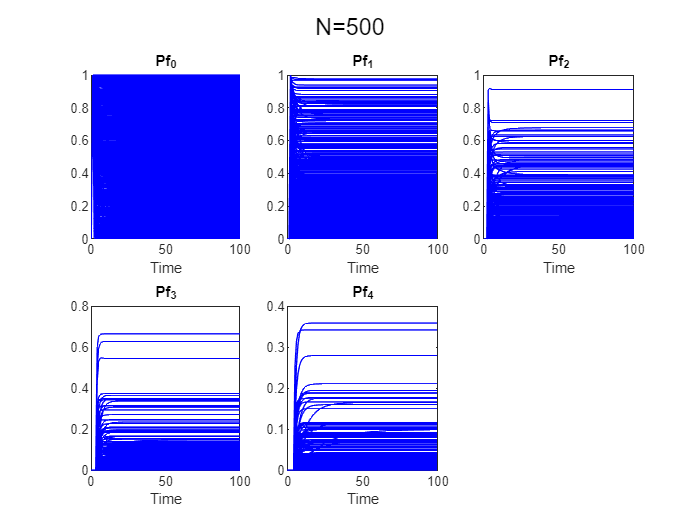

M=gsua_dmatrix(T,5e2);
y=gsua_eval(M',T,0:100);

## Parameter estimation

### Preparation of data

porcentajes1=[0.0874 0.1876 0.2469 0.2361 0.2414];%detection available data
sum(porcentajes1)

ans = 0.9994

fcurve=repmat(porcentajes1',1,10)%constant curves to estimate

fcurve =     0.0874    0.0874    0.0874    0.0874    0.0874    0.0874    0.0874    0.0874    0.0874    0.0874
    0.1876    0.1876    0.1876    0.1876    0.1876    0.1876    0.1876    0.1876    0.1876    0.1876
    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469    0.2469
    0.2361    0.2361    0.2361    0.2361    0.2361    0.2361    0.2361    0.2361    0.2361    0.2361
    0.2414    0.2414    0.2414    0.2414    0.2414    0.2414    0.2414    0.2414    0.2414    0.2414


### Estimation of parameters

Generating a valid matrix for estimations
Estimation 1

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 2

Local minimum found that satisfies t

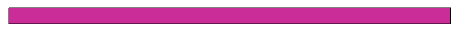

Estimation 1000

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Tp = 7×3 table
                Range     Nominal     Estfmincon  
                ______    _______    _____________

    \delta_0    0    1      0.5      1×1000 double
    \delta_1    0    1      0.5      1×1000 double
    \delta_2    0    1      0.5      1×1000 double
    \delta_3    0    1      0.5      1×1000 double
    \alpha_1    0    1      0.5      1×1000 double
    \alpha_2    0    1      0.5      1×1000 double
    \alpha_3    0    1      0.5      1×1000 double


Tp=gsua_pe(T,91:100,fcurve,'solver','fmincon','N',1e3)

### Estimation results

Plotting all estimations

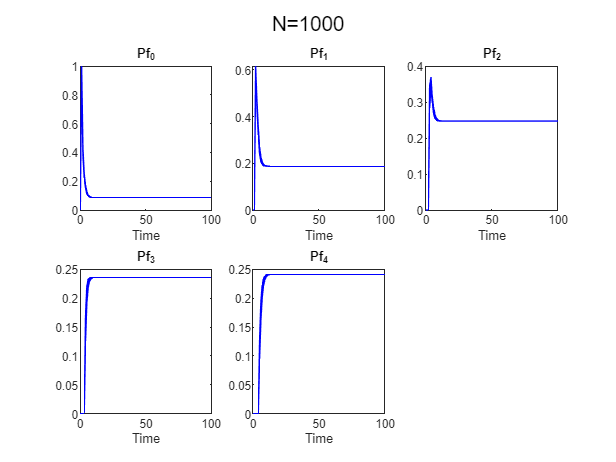

figure(1)
clf
gsua_eval(Tp.Estfmincon,T);

Plotting the better estimations

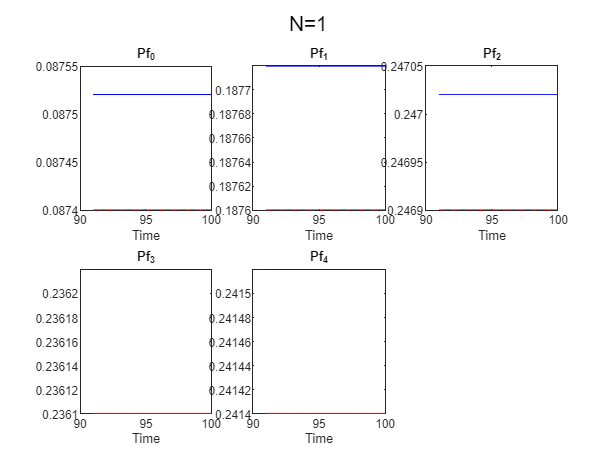

figure(2)
clf
gsua_eval(Tp.Estfmincon(:,1),T,91:100,fcurve1);

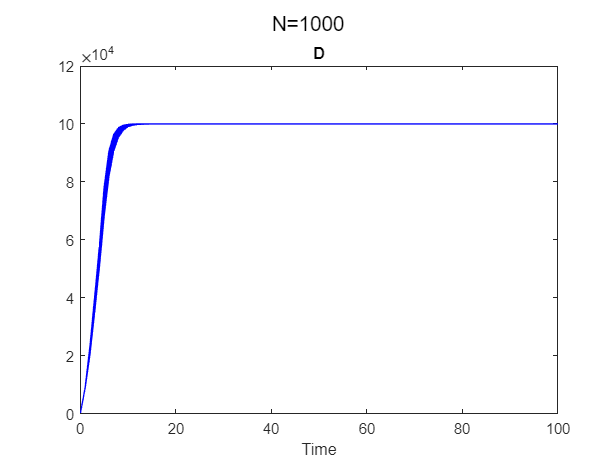

figure(3)
T.Properties.CustomProperties.output=10;
gsua_eval(Tp.Estfmincon,T);

estims=Tp.Estfmincon;
save("Esim_auxModel2.mat",'estims')

## Identifiability assessment

Histogram of estimated values for each parameter

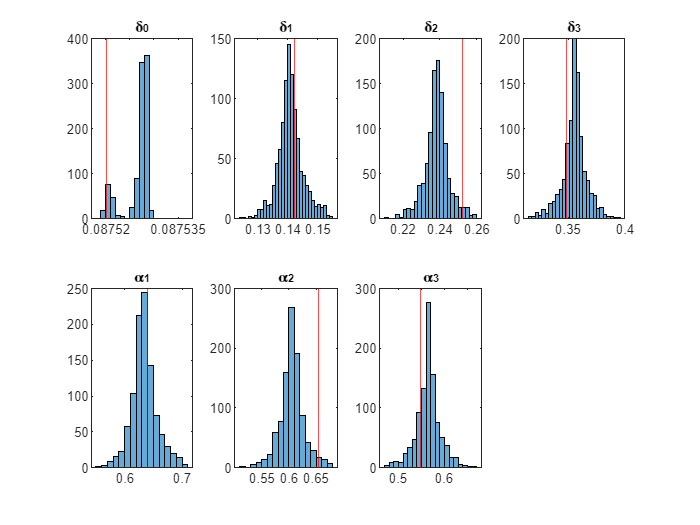

load Esim_auxModel2.mat
figure(10)
clf
for i=1:7
    subplot(2,4,i)
    histogram(estims(i,:))
    hold on
    xline(estims(i,1),'r')
    title(T.Properties.RowNames{i})
end

estims(:,1)

ans =     0.0875
    0.1422
    0.2525
    0.3489
    0.6398
    0.6532
    0.5479


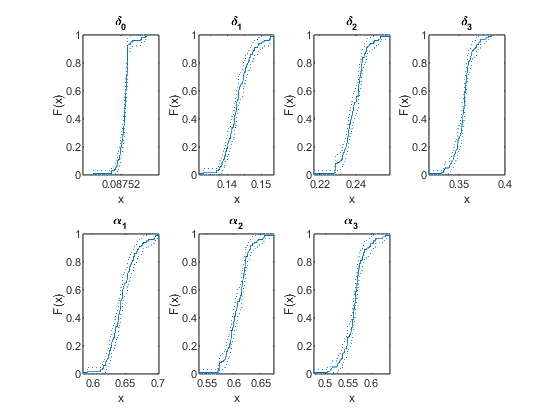

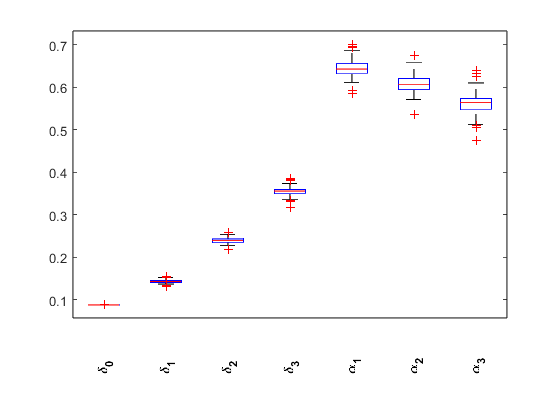

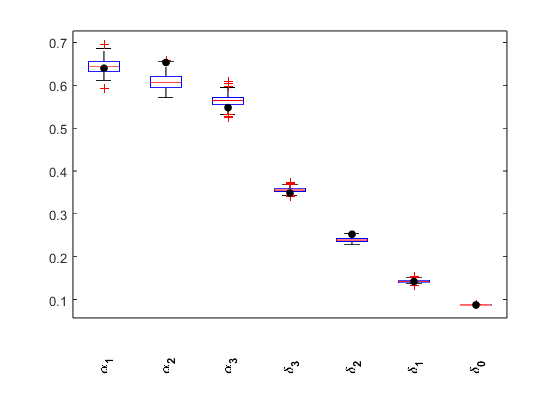

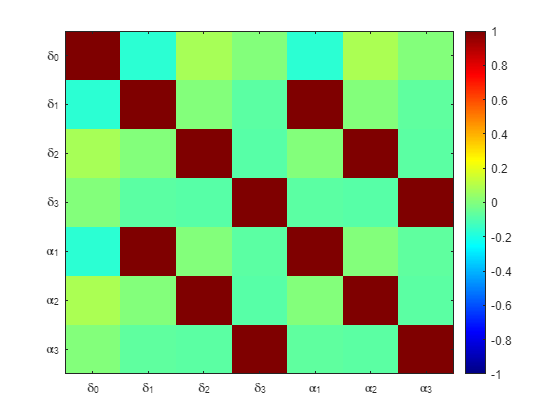

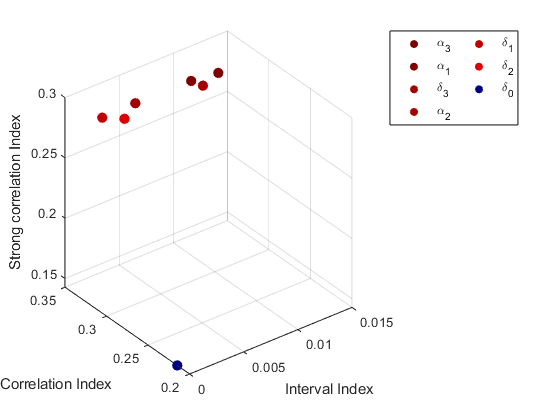

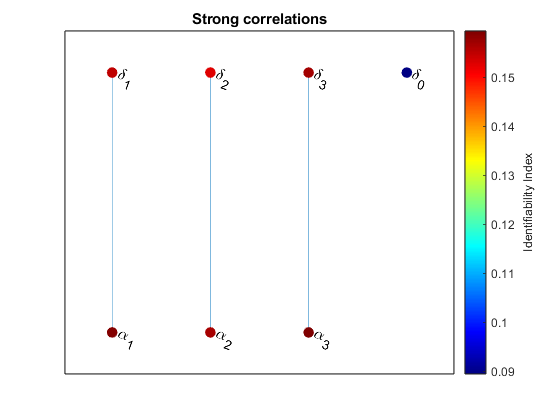

T = 7×4 table
                      Range           Nominal        Est          index 
                __________________    _______    ____________    _______

    \delta_0    0.08752    0.08752    0.08752    1×100 double    0.08942
    \delta_1    0.14178    0.14371    0.14275    1×100 double    0.15498
    \delta_2    0.23736    0.24049    0.23893    1×100 double     0.1528
    \delta_3    0.35315    0.35821    0.35568    1×100 double    0.15678
    \alpha_1    0.63781    0.64797    0.64289    1×100 double    0.15915
    \alpha_2    0.60193    0.61238    0.60715    1×100 double     0.1567
    \alpha_3     0.5582    0.57061     0.5644    1×100 double    0.15944


Tia=gsua_ia(T,estims(:,1:100),true,false,true);

## Uncertainty analysis for intervals of best estimations

T2=T;
T2.Range=[min(estims(:,1:100),[],2),max(estims(:,1:100),[],2)];
T2.Nominal=estims(:,1)

T2 = 7×2 table
                       Range            Nominal
                ____________________    _______

    \delta_0    0.087519    0.087521    0.08752
    \delta_1     0.13155     0.15379    0.14216
    \delta_2      0.2169     0.25868    0.25249
    \delta_3     0.31749     0.38515    0.34892
    \alpha_1     0.58481     0.70169    0.63982
    \alpha_2     0.53568     0.67487    0.65325
    \alpha_3     0.47562     0.64048    0.54794


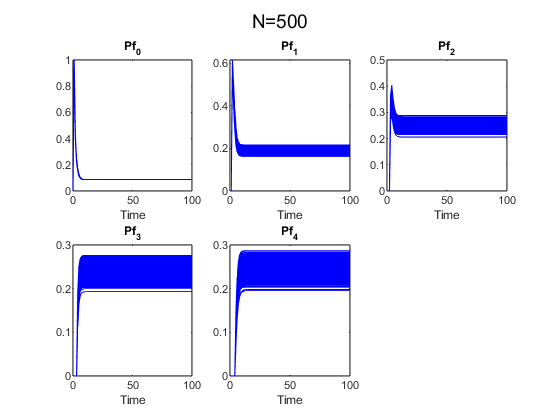

M=gsua_dmatrix(T2,5e2);
y=gsua_eval(M',T2,0:100);